# Constants & Building the grid

clc
clear
z0 = 1;
zmax = 10*z0;
N = 2^10;   %Grid size (# of points)
dz = zmax/N;
v = 0:1:N-1;
z = -zmax/2 + v*dz;
kmax = 2*pi/dz;
dk = kmax/N;
k = -kmax/2 + v*dk;
wt=0:0.1:100;
zeta = 0.05;    %Damping Amplitude

%%%%% Initial wavefunction %%%%%
    psi0 = exp(-0.5*((z-2*z0)./z0).^2);
    psi0 = psi0./sqrt(sum(abs(psi0).^2));
%%%%%%%%%%%%%%%%%%%

## Building Hamiltonian matrix h_m,v & find eigenvalues and eigenvectors

hmv = zeros(N);

for m = 1:N
for v = 1:N  
        if m == v
       hmv(m,v) = (1-1i*zeta)*(   (z0/dz)^2 + 0.5*(z(m)/z0)^2    );
        elseif m+1 == v || m-1 == v
        hmv (m,v) =(1-1i*zeta)* (   -0.5*(z0/dz)^2   );
        end     
end
end

[V,D] = eig(hmv);

## Time Evolution of the wavefunction by linear superposition of of the time-dependent expansion coofficients

psi=V';
c = psi0*conj(psi');
psit = zeros(N,length(wt));
for tt = 1:length(wt)
    for n = 1:length(c)
        psit(:,tt) = psit(:,tt)+ c(n).*psi(n,:)'.*exp(-1i*wt(tt)*D(n,n)); 
    end
    psit(:,tt) = psit(:,tt) ./ sqrt((sum(abs(psit(:,tt)).^2)));
end

## Fourier transform to k-space for the wavefunction at each time delay

psik = zeros(N,length(wt));
for tt = 1:length(wt) 
psik(:,tt) = ftxtop(psit(:,tt),dz,1);
 psik(:,tt) = psik(:,tt) ./ sqrt((sum(abs(psik(:,tt)).^2)));
end

## Calculating expectation values <z>,<k> , standard deviations Sigma_z , Sigma_k and uncetainty relation

Z = zeros(1,length(wt));
SigmaZ = zeros(1,length(wt));
P = zeros(1,length(wt));
K = zeros(1,length(wt));
SigmaP = zeros(1,length(wt));
SigmaK = zeros(1,length(wt));
Uncertainty = zeros(1,length(wt));

for tt = 1:length(wt)  
Z(tt) = z*(abs(psit(:,tt)).^2);
SigmaZ(tt) = sqrt(((z-Z(tt)).^2)*(abs(psit(:,tt)).^2));
K(tt) = k*(abs(psik(:,tt)).^2);
SigmaK(tt) = sqrt((((k-K(tt)).^2))*(abs(psik(:,tt)).^2));
Uncertainty(tt) = SigmaZ(tt) * SigmaK(tt);
end

## Plotting

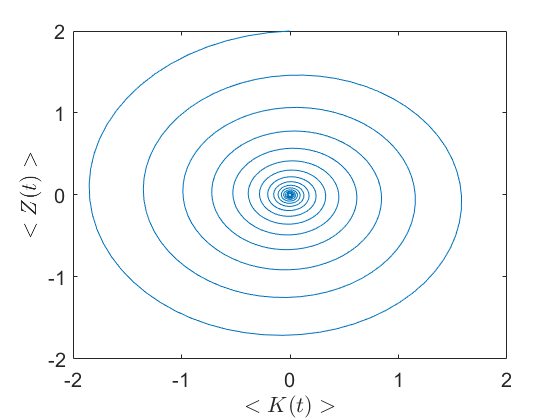

% Phase space plot <z> vs <k>
 figure(1)
plot(K,Z);
set(gca,'FontSize',15);
        xlabel('$<K(t)>$','interpreter','latex')
        ylabel('${<Z(t)>}$','interpreter','latex')

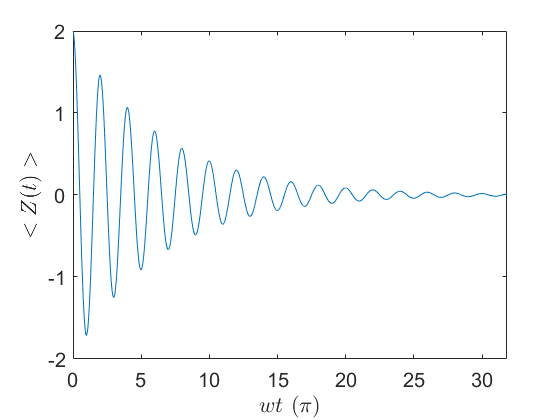

 
 % Position expectation value <z> vs wt
 figure(2)
plot(wt/(pi),Z);
set(gca,'FontSize',15);
        xlabel('$wt \ (\pi)$','interpreter','latex')
        ylabel('${<Z(t)>}$','interpreter','latex')

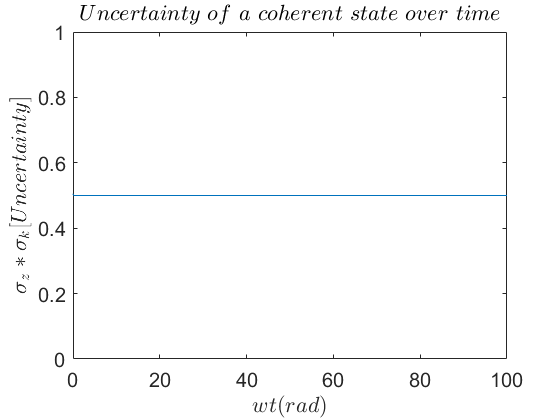


% Uncertainty of z,k vs wt
figure(3)
plot(wt,Uncertainty);
        set(gca,'FontSize',15);
           axis([min(wt) max(wt) 0 1])
        xlabel('$wt (rad)$','interpreter','latex')
        ylabel('${\sigma_z * \sigma_k} [Uncertainty] $','interpreter','latex')
title('$Uncertainty \ of \ a \ coherent \ state \  over \ time$','interpreter','latex')

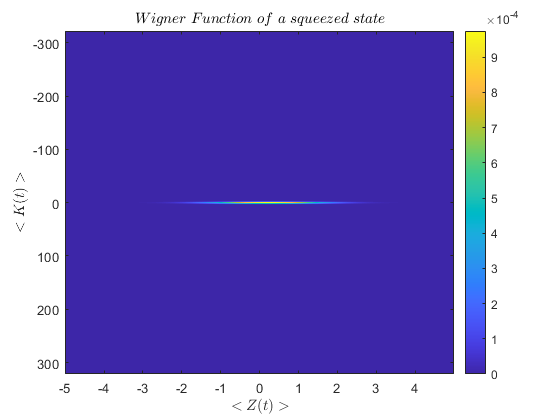


%Wigner function(z,k)  at wt =157
y = psit(:,wt == 50)';
rho = y'*y;
rho_rotated =imrotate(rho,45,'bicubic','crop');
wigner = real(ftxtop(rho_rotated,dz,1));
wigner = wigner/sum(wigner,'all');

figure(4)
imagesc(z,k,wigner);
colorbar
xlabel('$<Z(t)>$','interpreter','latex')
        ylabel('${<K(t)>}$','interpreter','latex')
title('$Wigner \ Function \ of \ a \ squeezed \ state$','interpreter','latex')

function [fp] = ftxtop(fx,dx,hbar)

% function ftptox computes the fourier transform fp 
% (a wavfunction in the momentum variable p)  of the position 
% wavefunction fx.  Constants are chosen such that normalization
% is preserved.  The definitions of the fourier transform and inverse 
% transform assumed here have a coefficient of sqrt(1/(2*pi*hbar))
% for both the transform and inverse transform integrals.
%
% dx is the grid spacing of the position array.
% hbar is treated as an input, so that by setting hbar=1, a
% function over wavenumber (k) can be obtained instead of the momentum
% wavefunction.  To work in standard (SI) units, set hbar=1.044e-34.

N  = length(fx);
fp = dx*(1/2/pi/hbar)^(1/2)*fftshift(fft(ifftshift(fx)));

end

function [fx] = iftptox(fp,dp,hbar)

% function iftptox computes the inverse fourier transform fx 
% (a wavfunction in the position variable x)  of the momentum 
% wavefunction fp.  Constants are chosen such that normalization
% is preserved.  The definitions of the fourier transform and inverse 
% transform assumed here have a coefficient of sqrt(1/(2*pi*hbar))
% for both the transform and inverse transform integrals.
%
% dp is the grid spacing of the momentum array.
% hbar is treated as an input, so that by setting hbar=1, a
% function over wavenumber (k) can be used instead of the momentum
% wavefunction.  To work in standard (SI) units, set hbar=1.044e-34.

N  = length(fp);
fx = (N)*dp*(1/2/pi/hbar)^(1/2)*ifftshift(ifft(fftshift(fp)));

end
